# More about frequencies resulting from the Fourier transform

[mikexcohen@gmail.com](mailto:mikexcohen@gmail.com)

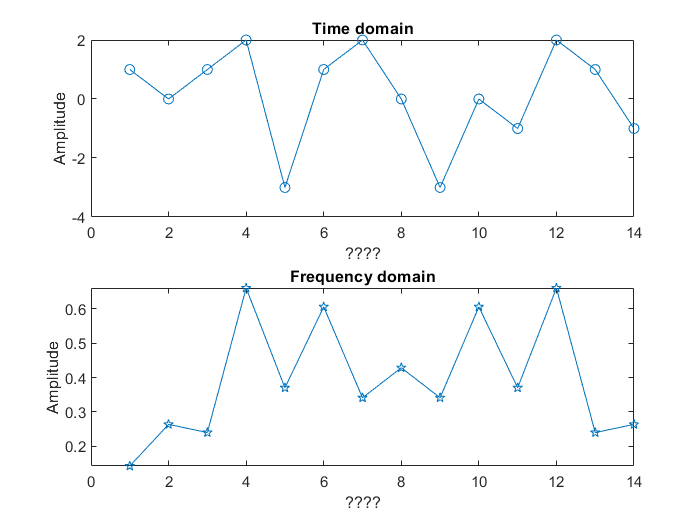

% a signal and take its fft
signal  = [ 1 0 1 2 -3 1 2 0 -3 0 -1 2 1 -1];
signalX = fft(signal) / length(signal);


% plot (without any frequency-axis scaling)
figure(1), clf
subplot(211)
plot(signal,'o-')
title('Time domain')
ylabel('Amplitude'), xlabel('????')

subplot(212)
plot(abs(signalX),'p-')
title('Frequency domain')
ylabel('Amplitude'), xlabel('????')

## same as above but time units are defined

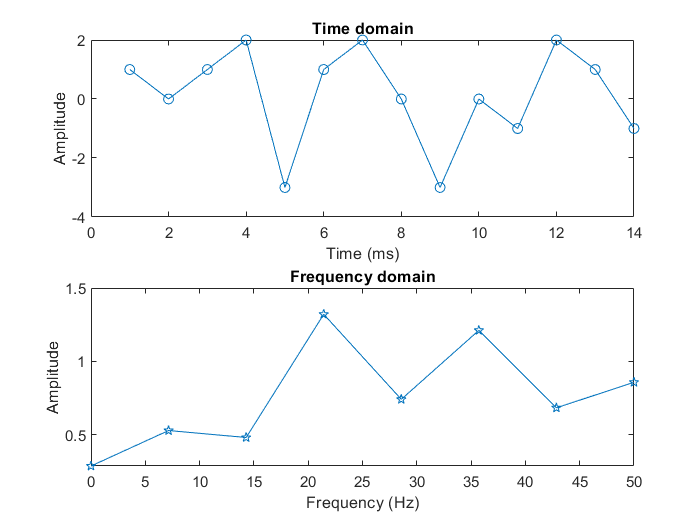

srate = 100; % in Hz
hz = linspace( 0, srate/2, floor(length(signal)/2)+1 );

figure(2), clf

% same plot as above
subplot(211)
plot(signal,'o-')
title('Time domain')
ylabel('Amplitude'), xlabel('Time (ms)')


% keep only positive frequencies
signalX = signalX(1:length(hz));

% similar plot as above, but with an x-axis label
subplot(212)
plot(hz,2*abs(signalX),'p-')
title('Frequency domain')
ylabel('Amplitude'), xlabel('Frequency (Hz)')

## DC reflects the mean offset

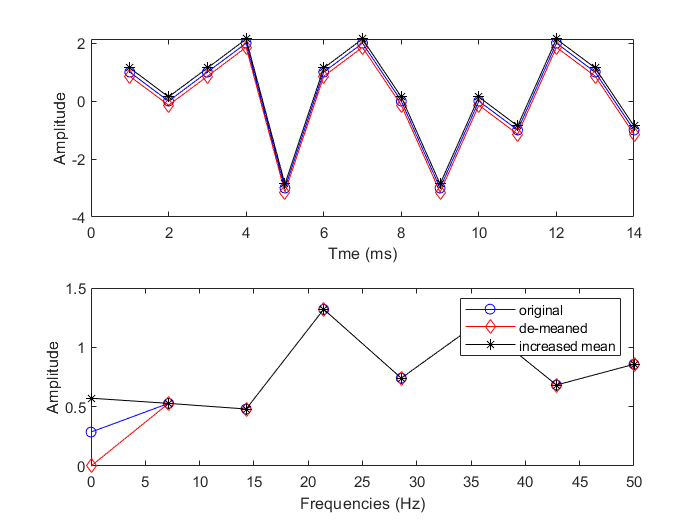

figure(3), clf

% compute the FFT of the same signal with different DC offsets
signalX1 = fft(signal) / length(signal);
signalX2 = fft(signal-mean(signal)) / length(signal);
signalX3 = fft(signal+mean(signal)) / length(signal);


% plot signals in the time domain
subplot(211)
plot(ifft(signalX1)*length(signal),'bo-'), hold on
plot(ifft(signalX2)*length(signal),'rd-'), hold on
plot(ifft(signalX3)*length(signal),'k*-'), hold on
xlabel('Tme (ms)'), ylabel('Amplitude')


% plot signals in the frequency domain
subplot(212)
plot(hz,2*abs(signalX1(1:length(hz))),'bo-'), hold on
plot(hz,2*abs(signalX2(1:length(hz))),'rd-')
plot(hz,2*abs(signalX3(1:length(hz))),'k*-')

xlabel('Frequencies (Hz)'), ylabel('Amplitude')
legend({'original';'de-meaned';'increased mean'})

## difference between sampling rate and number of time points for Fourier frequencies

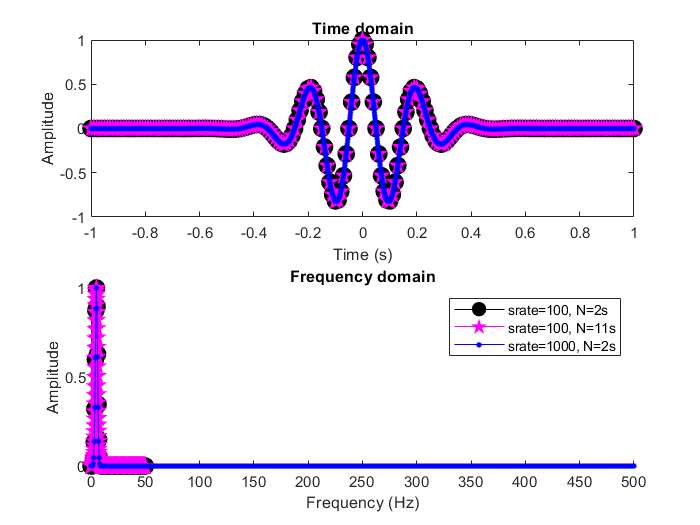

% temporal parameters
srates  = [100 100 1000]; % sampling rate
timedur = [  1  10    1]; % time points


freq    =     5; % in Hz
colors  = 'kmb';
symbols = 'op.';


figure(4), clf
legendText = cell(size(timedur));
for parami=1:length(colors)
    
    % define sampling rate in this round
    srate = srates(parami); % in Hz
    
    % define time
    time = -1:1/srate:timedur(parami);
    
    % create signal (Morlet wavelet)
    signal = cos(2*pi*freq.*time) .* exp( (-time.^2) / .05 );
    
    % compute FFT and normalize
    signalX = fft(signal)/length(signal);
    signalX = signalX./max(signalX);
    
    % define vector of frequencies in Hz
    hz = linspace( 0, srate/2, floor(length(time)/2)+1 );
    
    
    % plot time-domain signal
    subplot(211)
    plot(time,signal,[colors(parami) symbols(parami) '-'],'markersize',10,'markerface',colors(parami)), hold on
    set(gca,'xlim',[-1 1])
    xlabel('Time (s)'), ylabel('Amplitude')
    title('Time domain')
    
    % plot frequency-domain signal
    subplot(212), hold on
    plot(hz,abs(signalX(1:length(hz))),[colors(parami) symbols(parami) '-'],'markersize',10,'markerface',colors(parami))
    xlabel('Frequency (Hz)'), ylabel('Amplitude')
    title('Frequency domain')
    
    legendText{parami} = [ 'srate=' num2str(srates(parami)) ', N=' num2str(timedur(parami)+1) 's' ];
end

legend(legendText)

## zero-padding

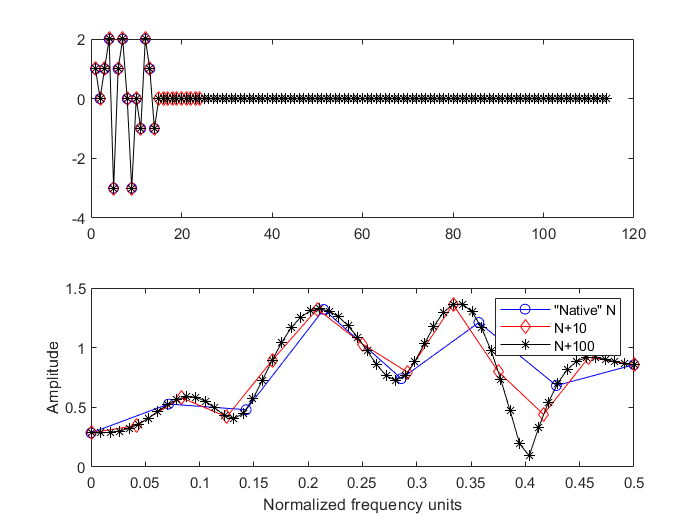

figure(5), clf

signal  = [ 1 0 1 2 -3 1 2 0 -3 0 -1 2 1 -1];

% compute the FFT of the same signal with different DC offsets
signalX1 = fft(signal,length(signal))     / length(signal);
signalX2 = fft(signal,length(signal)+10)  / length(signal);
signalX3 = fft(signal,length(signal)+100) / length(signal);

% define frequencies vector (sampling rate = 1)
frex1 = linspace( 0, .5, floor(length(signalX1)/2)+1 );
frex2 = linspace( 0, .5, floor(length(signalX2)/2)+1 );
frex3 = linspace( 0, .5, floor(length(signalX3)/2)+1 );


% plot signals in the time domain
subplot(211)
plot(ifft(signalX1)*length(signal),'bo-'), hold on
plot(ifft(signalX2)*length(signal),'rd-'), hold on
plot(ifft(signalX3)*length(signal),'k*-'), hold on


% plot signals in the frequency domain
subplot(212)
plot(frex1,2*abs(signalX1(1:length(frex1))),'bo-'), hold on
plot(frex2,2*abs(signalX2(1:length(frex2))),'rd-')
plot(frex3,2*abs(signalX3(1:length(frex3))),'k*-')

xlabel('Normalized frequency units'), ylabel('Amplitude')
legend({'"Native" N';'N+10';'N+100'})

## end.